## 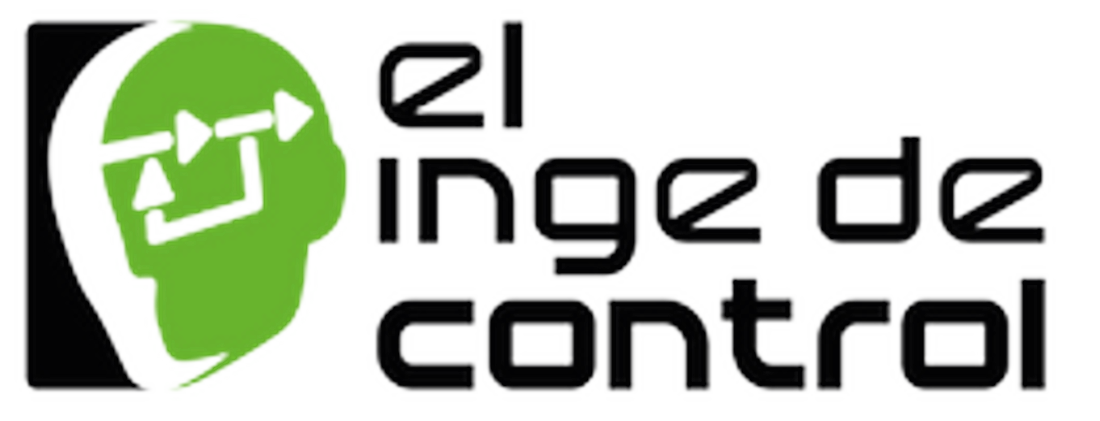

# **Taller: Control Robusto y Estocástico**

## Tema: Modelando las incertidumbres

## Dr. Julio A. García Rodríguez

Use the `ureal` uncertain element to represent real numbers whose values are uncertain when modeling dynamic systems with uncertainty. An uncertain real parameter has a nominal value, stored in the `NominalValue` property, and an uncertainty, which is the potential deviation from the nominal value. `ureal` stores this deviation equivalently in three different properties: `PlusMinus, Range and Percentage.`

clc, clear all, close all

delta1 = ureal('delta1',2);
delta2 = ureal('delta2',2,'Percentage',[-10 20]);

get(delta1)
get(delta2)

You can create an uncertain real parameter whose value can vary from 14 to 19, with a nominal value of 15.5. 

p1 = ureal('p1',15.5,'Range',[14,19])
get(p1)

Create an uncertain real parameter with a nominal value of 24, whose value can increase or decrease by 15%. 

k1 = ureal('k1',24,'Percentage',15)
get(k1)



**Exercise 1.**

Create a model of a second-order system with natural frequency w0 = 10 ±3 rad/s and a damping ratio that can vary from 0.5 to 0.8, with a nominal value of *ζ* = 0.6. First, represent the natural frequency and damping ratio values as uncertain real parameters.

% Parameters
w0 = ureal('w0',10,'PlusMinus',[-3 3]);
zeta = ureal('zeta',0.6,'Range',[0.5 0.8]);

% System
sys1 = tf(1,[1/w0^2 2*zeta/w0 1])
figure
step(sys1, 'm--', sys1.NominalValue,'r-')
legend('Uncertain', 'Nominal')



## LTI Models

**Exercise 2.**

Let us consider a two-input, two-output system described in the state space by the equations


$$\dot{x}=Ax+Bu \\
y=Cx+Du$$


where the matrices are next

A = [-1 0 5; 2 1 -4; -6 -3 -2]
B = [5 0; -4 1; 0 6]
C = [-1 0 -4; 2 3 6]
D = [3 -2; -4 1]
rank_CM = rank(ctrb(A, B))
rank_OM = rank(obsv(A, C))

This system is completely controllable and completely observable so that its state space model represents a minimal realization.

Gss = ss(A,B,C,D)
Gtf = tf(Gss)

p = pole(Gss)
z = tzero(Gss)
p = pole(Gtf)
z = tzero(Gtf)
G = ss(Gtf)
G = ss(Gtf,'min')

**Exercise 3 **

Insert the next two-input two-output. 

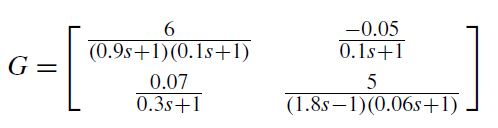


s = tf('s');
g11 = 6/((0.9*s + 1)*(0.1*s + 1));
g12 = -0.05/(0.1*s + 1);
g21 = 0.07/(0.3*s + 1);
g22 = 5/((1.8*s - 1)*(0.06*s+1));

The system is 

G = [g11 g12; g21 g22]

## **Students Intervention**

What is the order of the system?

sigma(G,{10^(-2) 10^3})
title('Plant singular values')
grid

**Exercise 4.**

Consider the 2×2 transfer function matrix

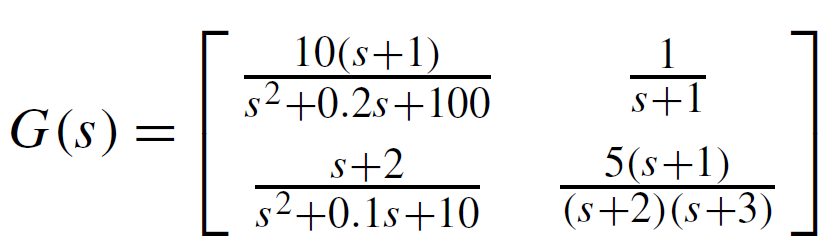

s = tf('s');
g11 = 10*(s + 1)/(s^2 + 0.2*s + 100);
g12 = 1/(s + 1);
g21 = (s + 2)/(s^2 + 0.1*s + 10);
g22 = 5*(s + 1)/((s + 2)*(s + 3));
G = [g11 g12 ;g21 g22];

figure
sigma(G,{10^0 10^2})
grid
norm(G,'inf')

**Exercise 5. **

The mass-damper-system.

The dynamics of such a system can be described by the following second order differential equation, by Newton’s Second Law

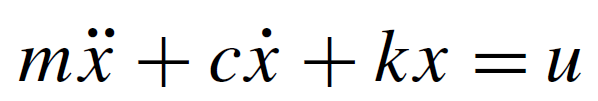

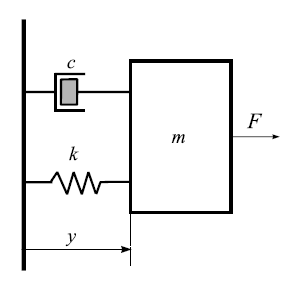

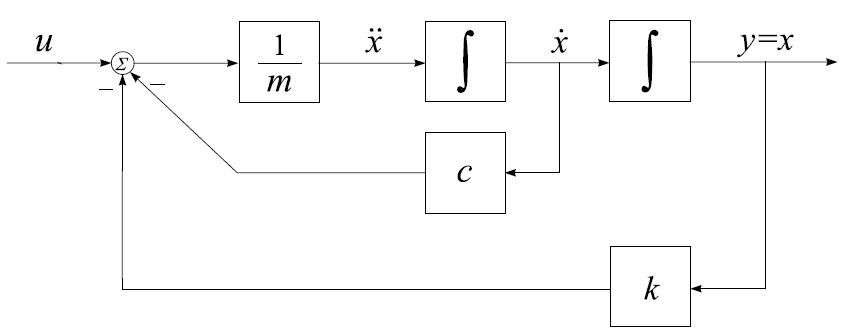

Denoting $x_1=x, \quad x_2=\frac{dx}{dt}$

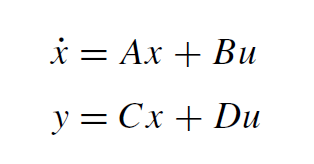        

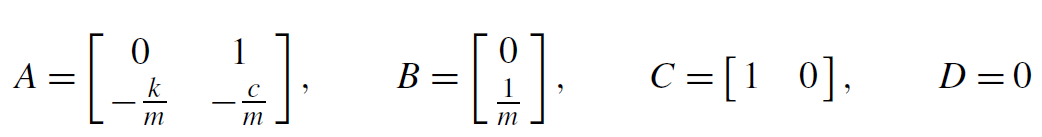

The transfer function is given by 

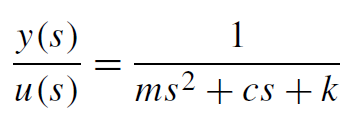

In a realistic system, the three physical parameters *m*, *c*, and *k* are not known exactly. However, it can be assumed that their values are within certain, known intervals. That is,

% Parameters
m = ureal('m',3,'Percentage',[-40, 40])
c = ureal('c',1,'Range',[0.8, 1.2])
k = ureal('k',2,'PlusMinus',[-0.6, 0.6])


% Uncertain system
A = [ 0 1; -k/m -c/m];
B = [0 1/m]';
C = [1 0];
D = 0;
uss1 = ss(A,B,C,D)


%Uncertain transfer function
uss2 = tf(1,[m,c,k])
% Using the function feedback
s = tf('s');
g1 = (1/s)/m;
int2 = 1/s;
uss3 = feedback(int2*feedback(g1,c),k)


% Properties of uncertain model
get(uss1)
uss1.Uncertainty
uss1.NominalValue
SYS_1=usubs(uss1,'m',3,'c',1,'k',2)


% Bode plot of the uncertain plant
w = logspace(-1,1,100);
figure
bode(uss1,w), grid
title('Bode plot of uncertain system')


% Step responses of the uncertain plant
figure
step(uss1), grid
title('Step responses of uncertain system')
% Uncertain frequency response
w = logspace(-1,1,200);
freqs = ufrd(uss1,w);
figure
bode(freqs), grid
title('Uncertain frequency response')
% Uncertain frequency response
figure
frres = ufrd(uss2,w)
nyquist(frres), grid
title('Nyquist diagram of uncertain system')
% Step response of the mass-damper-spring system
% for a grid of 50 values of uncertain parameters
figure
step(gridureal(uss3,50)), grid
title('Step response for a grid of 50 values of uncertain parameters')
